%clearvars

% data = load('C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\LocCam_calibration.mat');
% data;
% meer = data.stereoParams;
% meer;
% Params1 = meer.CameraParameters1;
% Params2 = meer.CameraParameters2;
% 
% images1 = make_images1('C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\all_LocCam', 'C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\all_LocCam\');

% fixed_point = 1 
% vSet1c = imageviewset;
% [stored_start2c, vSet2c, vSet1c, xyzPoints1c, index_of_used_stereo_imagec, stored_prevPoints2c, stored_prevFeatures2c, previous1c] = make_SFM(images1(1:100), fixed_point, 1, vSet1c);
% makeplot(vSet1c, xyzPoints1c)
% part 1, vSet1c has best solution


% [stored_start3, vSet3, vSet2, xyzPoints2, index_of_used_stereo_image2, stored_prevPoints3, stored_prevFeatures3, previous2] = make_SFM(images1(101:200), stored_start2c, 0, vSet2c, stored_prevPoints2c, stored_prevFeatures2c, previous1c, 100);
%makeplot(vSet2, xyzPoints2)

% part 2, vSet2 has best solution


% [stored_start4e, vSet4e, vSet3e, xyzPoints3e, index_of_used_stereo_image4e, stored_prevPoints4e, stored_prevFeatures4e, previous3e] = make_SFM(images1(201:300), stored_start3, 0, vSet3, stored_prevPoints3, stored_prevFeatures3, previous2, 200);
% makeplot(vSet3e, xyzPoints3e)

%part3 3, e is the best
% [stored_start5a, vSet5a, vSet4a, xyzPoints4a, index_of_used_stereo_image5a, stored_prevPoints5a, stored_prevFeatures5a, previous4a] = make_SFM(images1(301:400), stored_start4e, 0, vSet4e, stored_prevPoints4e, stored_prevFeatures4e, previous3e, 300);
% makeplot(vSet4a, xyzPoints4a)

%save('part4','-v7.3','-nocompression');


%makeplots(vSet1c, xyzPoints1c, vSet2, xyzPoints2, vSet3e, xyzPoints3e, vSet4a, xyzPoints4a)
% [stored_start6a, vSet6a, vSet5a, xyzPoints5a, index_of_used_stereo_image6a, stored_prevPoints6a, stored_prevFeatures6a, previous5a] = make_SFM(images1(401:500), stored_start5a, 0, vSet5a, stored_prevPoints5a, stored_prevFeatures5a, previous4a, 400);
% makeplot(vSet5a, xyzPoints5a)

%save('part6and7','-v7.3','-nocompression');
% [stored_start7a, vSet7a, vSet6aa, xyzPoints6aa, index_of_used_stereo_image7a, stored_prevPoints7a, stored_prevFeatures7a, previous6a] = make_SFM(images1(501:600), stored_start6a, 0, vSet6a, stored_prevPoints6a, stored_prevFeatures6a, previous5a, 500);
% makeplot(vSet6aa, xyzPoints6aa)
% 
% [stored_start8a, vSet8a, vSet7aa, xyzPoints7aa, index_of_used_stereo_image8a, stored_prevPoints8a, stored_prevFeatures8a, previous7a] = make_SFM(images1(601:700), stored_start7a, 0, vSet7a, stored_prevPoints7a, stored_prevFeatures7a, previous6a, 600);
% makeplot(vSet7aa, xyzPoints7aa)

whos
test = load('part6and7.mat')

images1 = test.images1
Params1 = test.Params1
Params2 = test.Params2
stored_start8a = test.stored_start8a
vSet8a = test.vSet8a
stored_prevPoints8a = test.stored_prevPoints8a
stored_prevFeatures8a = test.stored_prevFeatures8a
previous7a = test.previous7a

whos

[stored_start9a, vSet9a, vSet8aa, xyzPoints8aa, index_of_used_stereo_image9a, stored_prevPoints9a, stored_prevFeatures9a, previous8a] = make_SFM(images1(701:800), stored_start8a, 0, vSet8a, stored_prevPoints8a, stored_prevFeatures8a, previous7a, 700);
makeplot(vSet8aa, xyzPoints8aa)

[stored_start10a, vSet10a, vSet9aa, xyzPoints9aa, index_of_used_stereo_image10a, stored_prevPoints10a, stored_prevFeatures10a, previous9a] = make_SFM(images1(801:900), stored_start9a, 0, vSet9a, stored_prevPoints9a, stored_prevFeatures9a, previous8a, 800);
makeplot(vSet9aa, xyzPoints9aa)

[stored_start11a, vSet11a, vSet10aa, xyzPoints10aa, index_of_used_stereo_image11a, stored_prevPoints11a, stored_prevFeatures11a, previous10a] = make_SFM(images1(901:end), stored_start10a, 0, vSet10a, stored_prevPoints10a, stored_prevFeatures10a, previous9a, 900);
makeplot(vSet10aa, xyzPoints10aa)
save('part8,9and10','-v7.3','-nocompression');

save('sfm_data','-v7.3','-nocompression');


clear('yzPoints6aa')

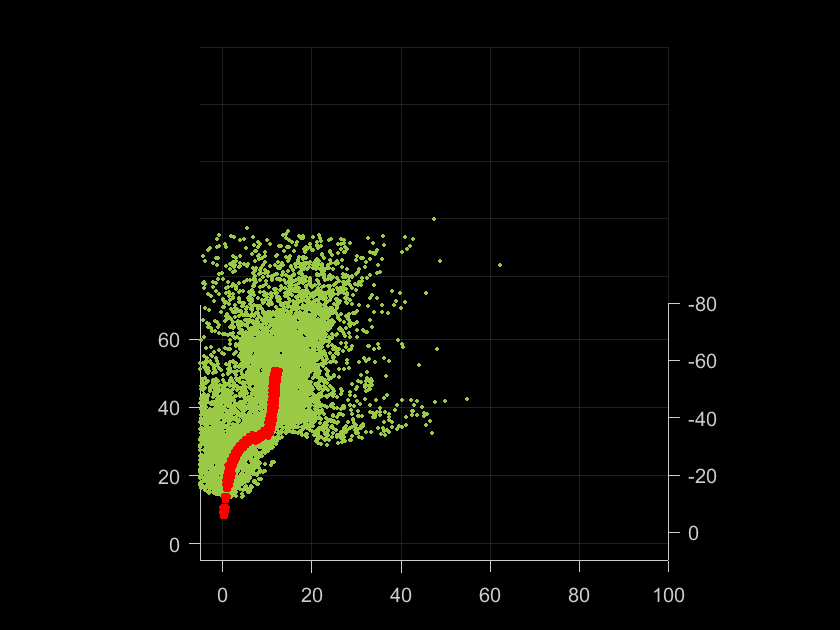

makeplot(test.vSet1c, test.xyzPoints1c)
view(0, -40)

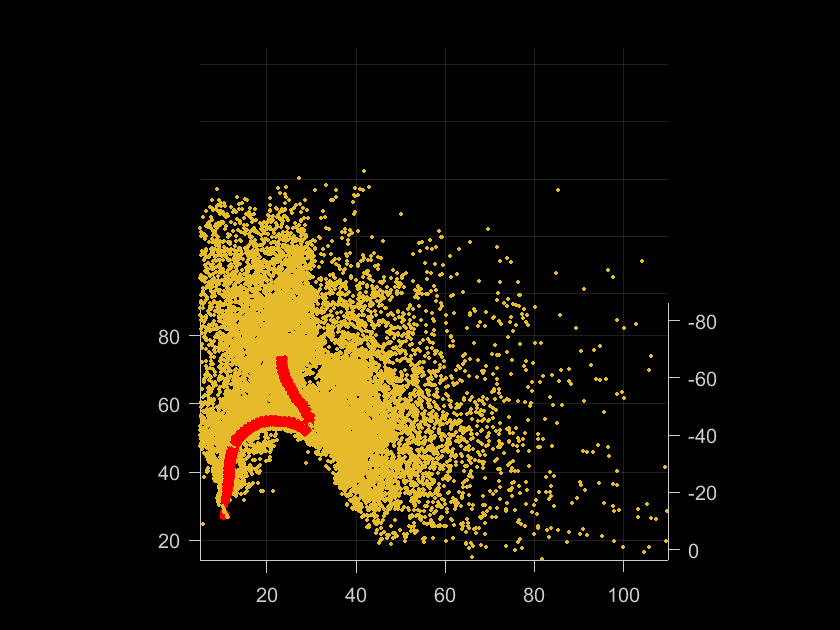

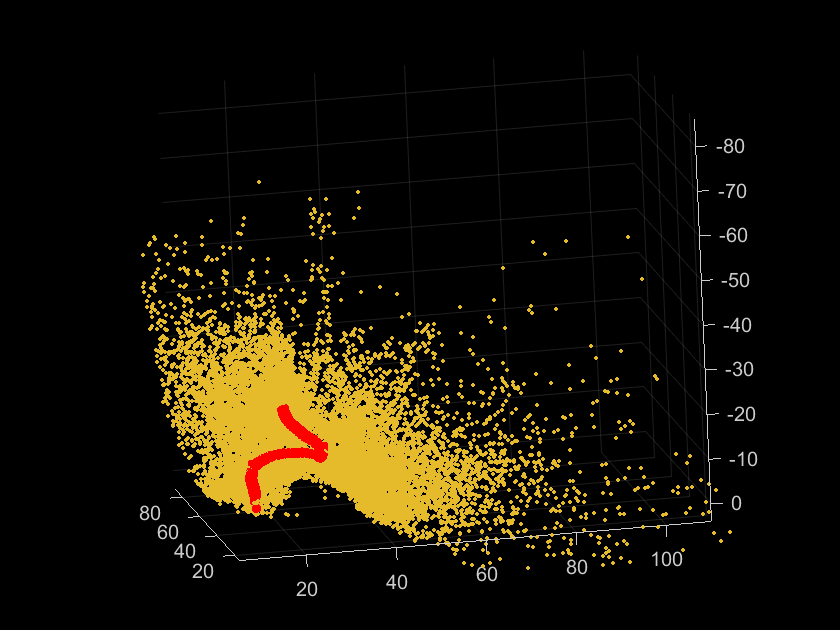


makeplot(test.vSet2, test.xyzPoints2)
view(0, -40)

test

test = struct with fields:
                                    I: [813×1155 uint8]
                              Params1: [1×1 cameraParameters]
                              Params2: [1×1 cameraParameters]
                                  ans: {[813×1155 uint8]}
                                  cam: [1×1 vision.graphics.Camera]
                             camPoses: [78×2 table]
                            camPoses1: [78×2 table]
                           camPoses10: [90×2 table]
                            camPoses2: [80×2 table]
                            camPoses3: [98×2 table]
                            camPoses4: [100×2 table]
                            camPoses5: [100×2 table]
                            camPoses6: [100×2 table]
                            camPoses7: [96×2 table]
                            camPoses8: [100×2 table]
                            camPoses9: [98×2 table]
                         cameraParams: [1×1 cameraParameters]
                    camera_po

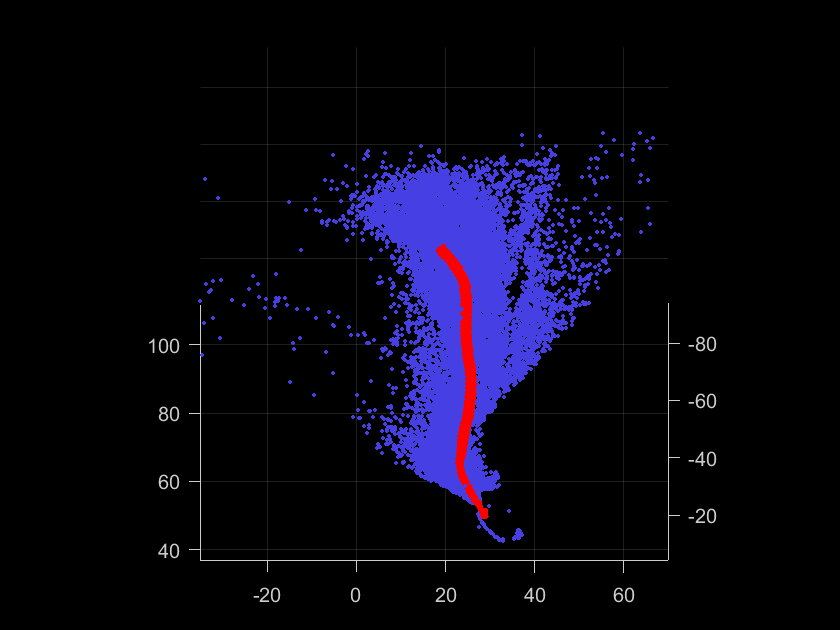

makeplot(test.vSet3e, test.xyzPoints3e)
view(0, -40)
xlim([-35, +70]);

% ylim([loc1(2)-80, loc1(2)+10]);
% zlim([loc1(3)-5, loc1(3)+70]);

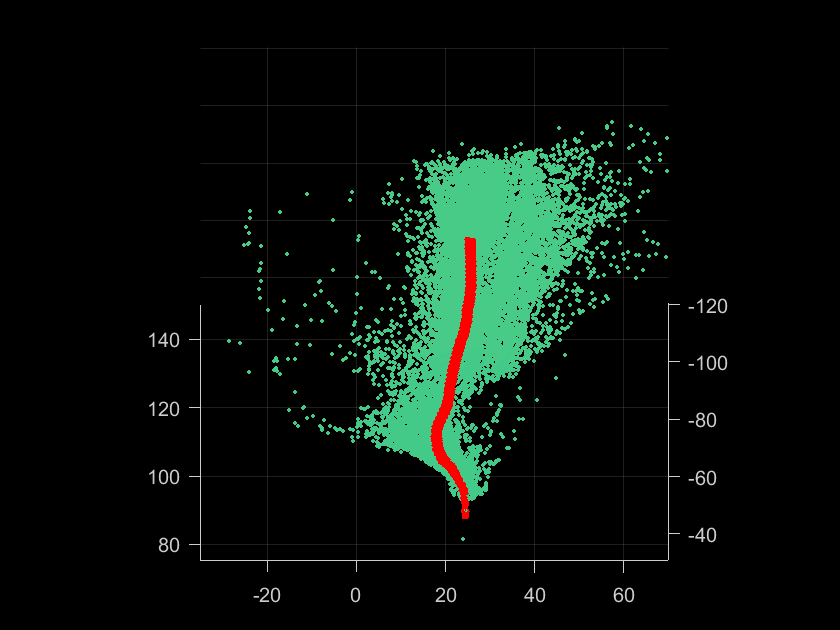

makeplot(test.vSet4a, test.xyzPoints4a)
view(0, -40)
xlim([-35, +70]);

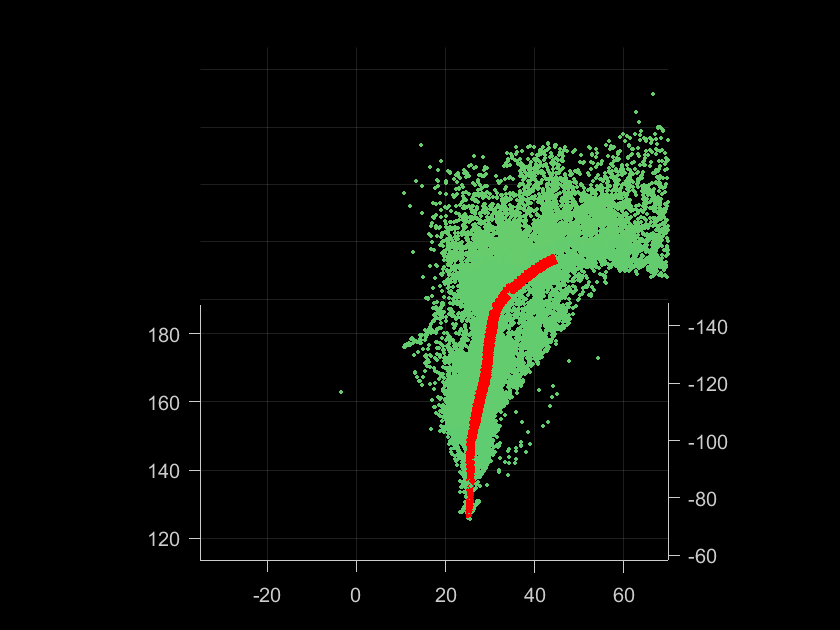

makeplot(test.vSet5a, test.xyzPoints5a)
view(0, -40)
xlim([-35, +70]);

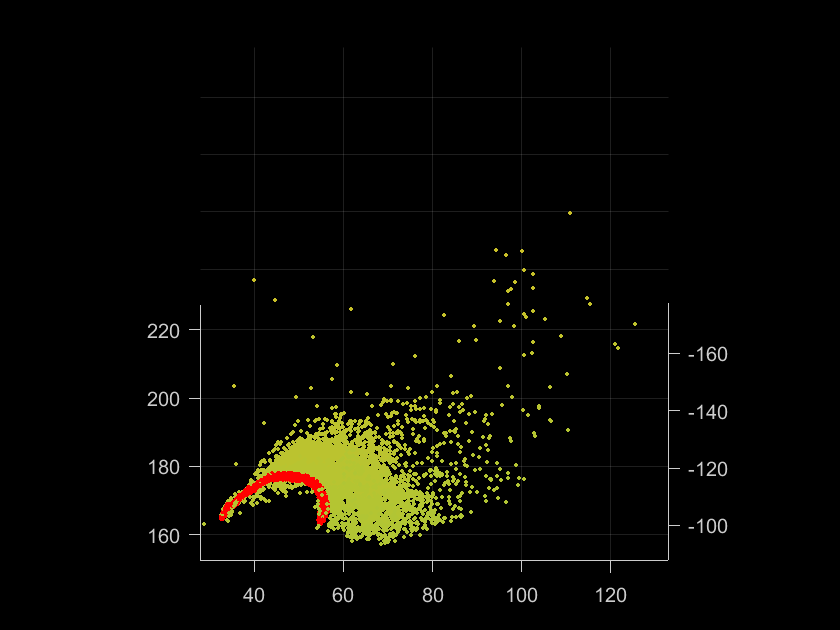

makeplot(test.vSet6aa, test.xyzPoints6aa)
view(0, -40)

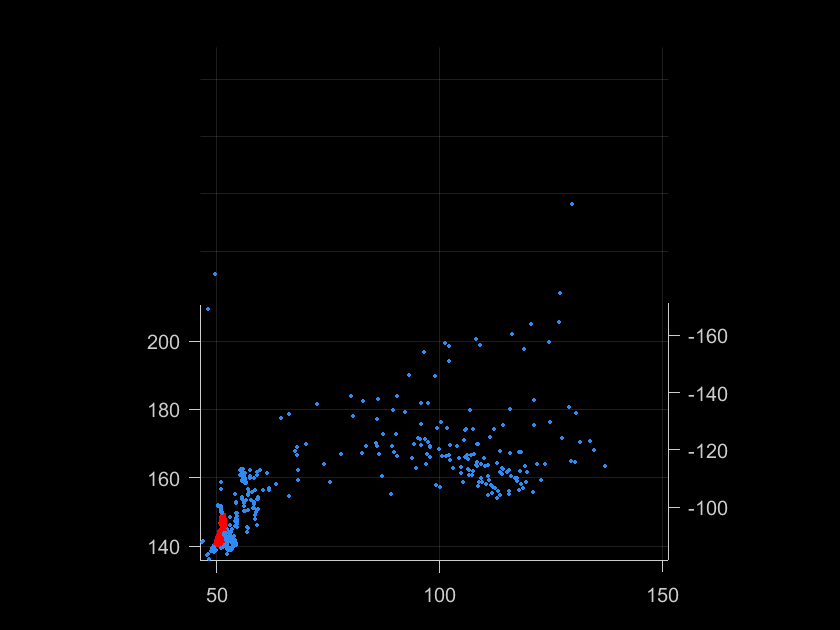

makeplot(test.vSet7aa, test.xyzPoints7aa)
view(0, -40)

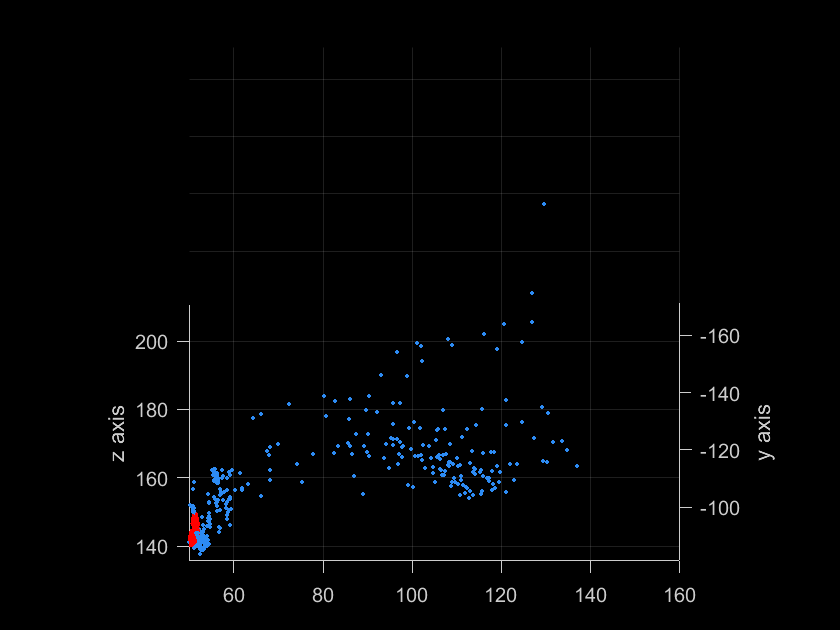

makeplot(test.vSet7aa, test.xyzPoints7aa)
view(0, -40)
xlim([5, +60]);
xlim([50, +160]);
ylabel('y axis')
zlabel('z axis')

makeplot(test.vSet8aa, test.xyzPoints8aa)
view(0, -40)
makeplot(test.vSet9aa, test.xyzPoints9aa)
view(0, -40)


% Display camera poses.
camPoses3 = poses(vSet3e);

test = camPoses3.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(xyzPoints3e, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses3.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-80, loc1(2)+10]);
zlim([loc1(3)-5, loc1(3)+70]);
camorbit(0, 0);


% Display camera poses.
camPoses4 = poses(vSet4a);

% Display camera poses.
camPoses3 = poses(vSet3e);

test = camPoses3.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(xyzPoints3e, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses3.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-80, loc1(2)+10]);
zlim([loc1(3)-5, loc1(3)+70]);
camorbit(10, 0);


% Display camera poses.
camPoses4 = poses(vSet4a);

% Display camera poses.
camPoses3 = poses(vSet3e);

test = camPoses3.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(xyzPoints3e, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses3.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-80, loc1(2)+10]);
zlim([loc1(3)-5, loc1(3)+70]);
view(0,0)



% Display camera poses.
camPoses3 = poses(vSet3e);

test = camPoses3.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(xyzPoints3e, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses3.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-80, loc1(2)+10]);
zlim([loc1(3)-5, loc1(3)+70]);
view(-90,0)

% Display camera poses.
camPoses4 = poses(vSet4a);

% Display camera poses.
camPoses3 = poses(vSet3e);

test = camPoses3.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(xyzPoints3e, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses3.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-80, loc1(2)+10]);
zlim([loc1(3)-5, loc1(3)+70]);
camorbit(0, 10);

% Display camera poses.
camPoses4 = poses(vSet4a);


% Display camera poses.
camPoses3 = poses(vSet3e);

test = camPoses3.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(xyzPoints3e, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses3.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-80, loc1(2)+10]);
zlim([loc1(3)-5, loc1(3)+70]);
camorbit(0, -10);

% Display camera poses.
camPoses4 = poses(vSet4a);


test = camPoses4.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(xyzPoints4a, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses4.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-80, loc1(2)+10]);
zlim([loc1(3)-5, loc1(3)+70]);
camorbit(0, -30);


makeplot(vSet5a, xyzPoints5a)

% Display camera poses.
camPoses6 = poses(vSet6aa);

test = camPoses6.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(xyzPoints6aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses6.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-60, loc1(2)+30]);
zlim([loc1(3)-60, loc1(3)+20]);
camorbit(0, -30);

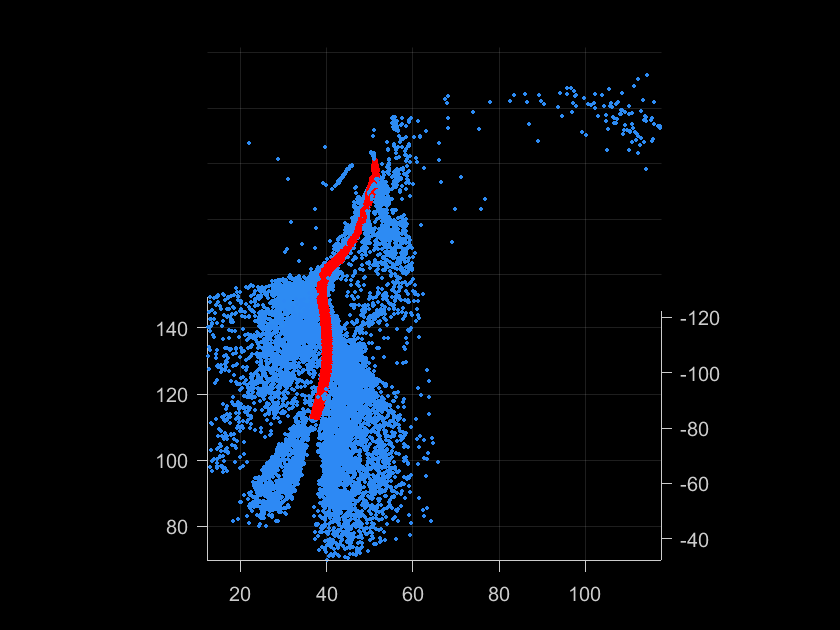


% Display camera poses.
camPoses7 = poses(test.vSet7aa);

test7 = camPoses7.AbsolutePose;
figure;

for i = 1: length(test7)
    cam = plotCamera('AbsolutePose',test7(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(test.xyzPoints7aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = test.camPoses7.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-40, loc1(2)+50]);
zlim([loc1(3)-60, loc1(3)+20]);
view(0, -40)

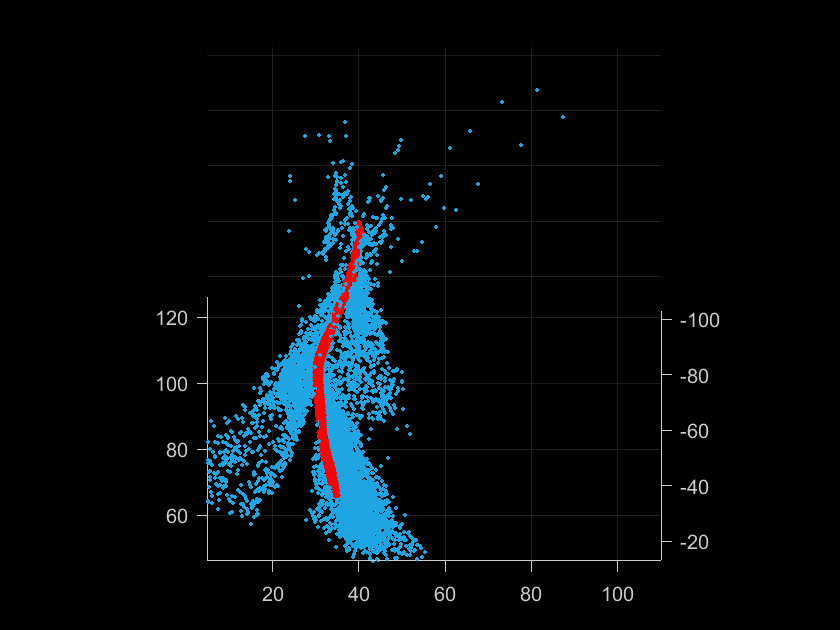



% Display camera poses.
camPoses8 = poses(test.vSet8aa);

test8 = camPoses8.AbsolutePose;
figure;

for i = 1: length(test8)
    cam = plotCamera('AbsolutePose',test8(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(test.xyzPoints8aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses8.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-40, loc1(2)+50]);
zlim([loc1(3)-60, loc1(3)+20]);
view(0, -40)

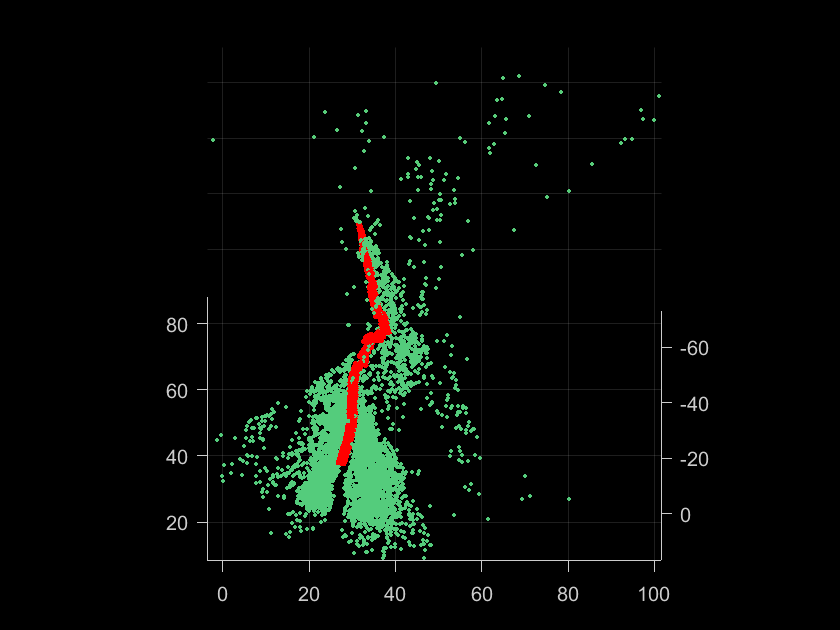


% Display camera poses.
camPoses9 = poses(test. vSet9aa);
test9 = camPoses9.AbsolutePose;
figure;

for i = 1: length(test9)
    cam = plotCamera('AbsolutePose',test9(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(test.xyzPoints9aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses9.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-40, loc1(2)+50]);
zlim([loc1(3)-60, loc1(3)+20]);
view(0, -40)

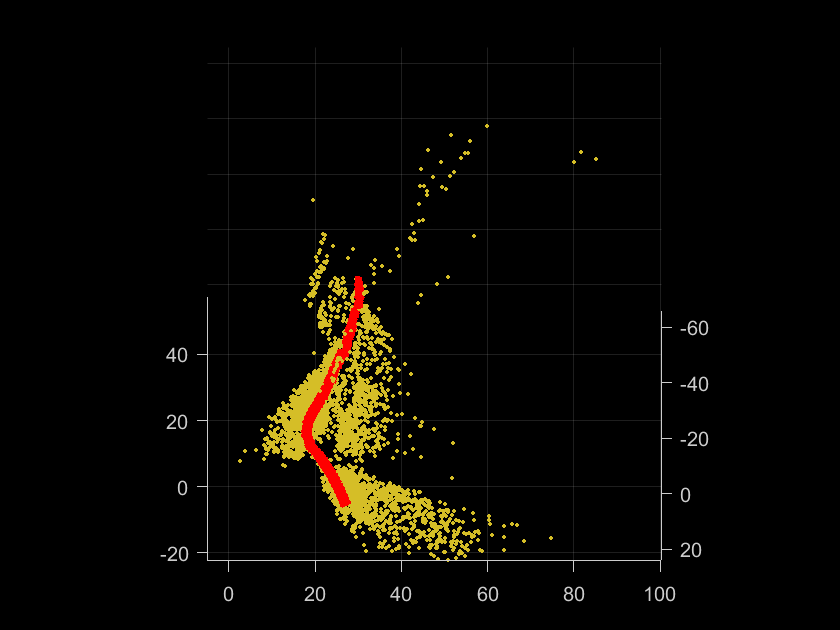


% Display camera poses.
camPoses10 = poses(test.vSet10aa);
test10 = camPoses10.AbsolutePose;
figure;

for i = 1: length(test10)
    cam = plotCamera('AbsolutePose',test10(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(test.xyzPoints10aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses10.AbsolutePose(1).Translation;
xlim([loc1(1)-35, loc1(1)+70]);
ylim([loc1(2)-60, loc1(2)+30]);
zlim([loc1(3)-60, loc1(3)+20]);
view(0, -40)


camPoses = poses(vSet1c);
test = camPoses.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints1c, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses2 = poses(vSet2);
test = camPoses2.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints2, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses3 = poses(vSet3e);
test = camPoses3.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints3e, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses4 = poses(vSet4a);
test = camPoses4.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints4a, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses5 = poses(vSet5a);
test = camPoses5.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints5a, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses6 = poses(vSet6aa);
test = camPoses6.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints6aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses7 = poses(vSet7aa);
test = camPoses7.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints7aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses8 = poses(vSet8aa);
test = camPoses8.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints8aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses9 = poses(vSet9aa);
test = camPoses9.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints9aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses10 = poses(vSet10aa);
test = camPoses10.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints10aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on


hold off

% Specify the viewing volume.

loc1 = camPoses.AbsolutePose(1).Translation;
xlim([loc1(1)-5, loc1(1)+60]);
ylim([loc1(2)-160, loc1(2)+35]);
zlim([loc1(3)-50, loc1(3)+200]);
view(0,0)



camPoses = poses(vSet1c);
test = camPoses.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints1c, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses2 = poses(vSet2);
test = camPoses2.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints2, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses3 = poses(vSet3e);
test = camPoses3.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints3e, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses4 = poses(vSet4a);
test = camPoses4.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints4a, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses5 = poses(vSet5a);
test = camPoses5.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints5a, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses6 = poses(vSet6aa);
test = camPoses6.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints6aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses7 = poses(vSet7aa);
test = camPoses7.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints7aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses8 = poses(vSet8aa);
test = camPoses8.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints8aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses9 = poses(vSet9aa);
test = camPoses9.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints9aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on

camPoses10 = poses(vSet10aa);
test = camPoses10.AbsolutePose;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end

% Display the 3-D points.
pcshow(xyzPoints10aa, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', ...
'MarkerSize', 25);
grid on


hold off

% Specify the viewing volume.

loc1 = camPoses.AbsolutePose(1).Translation;
xlim([loc1(1)-5, loc1(1)+60]);
ylim([loc1(2)-160, loc1(2)+35]);
zlim([loc1(3)-20, loc1(3)+200]);
view(-90, 0)






% Display camera poses.
camPoses2 = poses(vSet2)

% must include directory_of_images_small, vSet1, index_of_used_stereo_image


camPoses = poses(vSet1);

% index_of_used_stereo_image contain the number of the left images which
% have a high enough accuracy, these are uneven
index_of_used_stereo_image

%makes a list and computes the distance between the left and right camera
skip = 0;
distance = [];
for i = 1:height(camPoses)
    if skip == 1
        skip = 0;
        continue        
    end
    distance = [distance, norm(camPoses.AbsolutePose(i).Translation-camPoses.AbsolutePose(i+1).Translation)];
    skip = 1;
end
distance

mean(distance)

%camera pair are considered outliers if their distance differs more than 30% of the averag. 
% The index of their distance is the same index as the left camera has in index_of_used_stereo_image
filtered_distance = [];
index_which_need_to_be_removed = [];
for i = 1:length(distance)
    if distance(i) < .7*mean(distance) || distance(i) > 1.3*mean(distance)
        index_which_need_to_be_removed = [index_which_need_to_be_removed, i];
        continue
    end
    filtered_distance = [filtered_distance, distance(i)];
end

index_which_need_to_be_removed
filtered_distance 

%remove the indexes of stereoimages which do not have a high accuracy
index_of_used_stereo_image
good_indexes = [];
for i = 1:length(index_of_used_stereo_image)
    if ismember(i,index_which_need_to_be_removed)
        continue
    end
    good_indexes = [good_indexes, index_of_used_stereo_image(i)];
end
good_indexes

% The good indexes are the indexes of of the images which have a high
% enough degree of accuracy.
% This piece of code makes a list of the image directory's of the images of
% which there is a rigid3D with a high accuracy.
directory_of_images_small;
ultimately_used_image_directory = [];
for i = 1:length(directory_of_images_small)
    if ismember(i, good_indexes)
        ultimately_used_image_directory = [ultimately_used_image_directory, directory_of_images_small(i)];
    end
end
ultimately_used_image_directory

twelve_cm = mean(filtered_distance)
once_cm = twelve_cm/12
one_meter = once_cm*100

% Factor with which to mulitply to get everything in meters.
factor = 1/one_meter

new_camposes = camPoses;
meter_positions = []
six_cm = [0.06 0 0];

% New_camposes, is in meters.
for i =1:height(new_camposes)
    new_camposes.AbsolutePose(i).Translation = new_camposes.AbsolutePose(i).Translation*factor;
    new_camposes.AbsolutePose(i).Translation = new_camposes.AbsolutePose(i).Translation - six_cm;
    meter_positions = [meter_positions, new_camposes.AbsolutePose(i)];
end
% a is the distance between the first two camera
a = new_camposes.AbsolutePose(2).Translation
norm(a)
new_camposes.AbsolutePose(2)


ids = new_camposes.ViewId;

rigi3d_left_and_right = [];
for i = 1:height(new_camposes)
    camera_id = ids(i);
    if ismember(camera_id , good_indexes)
        rigi3d_left_and_right = [rigi3d_left_and_right, new_camposes.AbsolutePose(i)];
    elseif ismember(camera_id -1, good_indexes)
        rigi3d_left_and_right = [rigi3d_left_and_right, new_camposes.AbsolutePose(i)];
    end
end
rigi3d_left_and_right
rigi3d_left_and_right(1)

rigi3d_left_and_right(1).Translation
rigi3d_left_and_right(2).Translation

together = (rigi3d_left_and_right(1).Translation + rigi3d_left_and_right(2).Translation)
final_translation = together/2

rigi3d_left_and_right

final_camera_positions = [];
left = 1;
for i = 1:length(rigi3d_left_and_right)
    % if left than one should get the average of i and i+1
    if left == 1
        translation = (rigi3d_left_and_right(i).Translation + rigi3d_left_and_right(i+1).Translation)/2;
        rotation = rigi3d_left_and_right(i).Rotation;
        final_camera_positions = [final_camera_positions, rigid3d(rotation,translation)];
        left = 0;
    else
        left = 1;
    end
   
end
final_camera_positions

% these are the image directory's of which the pointclouds should be taken,
% the rigid3d positions as which calculated are their transformation
ultimately_used_image_directory

function [images1] = make_images1(location_file, common_directory)

all_data = load('C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\LocCam_calibration.mat');
stereParams_data = all_data.stereoParams;
Params1 = stereParams_data.CameraParameters1;
Params2 = stereParams_data.CameraParameters2;

LocCam_file = dir(location_file);
LocCam_image_names = {LocCam_file.name};
LocCam_image_names = LocCam_image_names(3:end);
directory_of_images = {};
%start at 3 because the 1 and 2, are fillers
for i = 1:length(LocCam_image_names)
    if mod(i,2) ~= 0
        name_image = LocCam_image_names(i);
        name_image = char(name_image);
        unique_directory = strcat(common_directory,name_image);
        directory_of_images = [directory_of_images, unique_directory];
    end
end

directory_of_images_small = {};
directory_of_images_small = [directory_of_images_small, directory_of_images(1)];

for i = 1:length(directory_of_images)
    if mod(i,10) == 0
        directory_of_images_small = [directory_of_images_small, directory_of_images(i)];
    end
end

%directory_of_images_small = directory_of_images_small(1:10);

image_counter = 1;
images1 = cell(1, length(directory_of_images_small)*2);
length(directory_of_images_small)
for i = 1:length(directory_of_images_small)
    i
    [left, right] = rectify(char(directory_of_images_small(i)));
    images1{image_counter} = left;
    image_counter  = image_counter + 1;
    
    images1{image_counter} = right;
    image_counter  = image_counter + 1;
end
end

function [orientation, location, inlierIdx, validPointFraction] = helperEstimateRelativePose(matchedPoints1, matchedPoints2, Params1, Params2)
if ~isnumeric(matchedPoints1)
    matchedPoints1 = matchedPoints1.Location;
end

if ~isnumeric(matchedPoints2)
    matchedPoints2 = matchedPoints2.Location;
end

for j = 1:100
    % Estimate the essential matrix.    
    [E, inlierIdx] = estimateEssentialMatrix(matchedPoints1,matchedPoints2, Params1, Params2);
    %[E, inlierIdx] = estimateEssentialMatrix(matchedPoints1, matchedPoints2,cameraParams);

    % Make sure we get enough inliers
    if sum(inlierIdx) / numel(inlierIdx) < .4
        continue;
    end
    
    % Get the epipolar inliers.
    inlierPoints1 = matchedPoints1(inlierIdx, :);
    inlierPoints2 = matchedPoints2(inlierIdx, :);    
    
    % Compute the camera pose from the fundamental matrix. Use half of the
    % points to reduce computation.
    [orientation, location, validPointFraction] = relativeCameraPose(E,Params1,Params2,inlierPoints1,inlierPoints2);
    %[orientation, location, validPointFraction] = relativeCameraPose(E, cameraParams, inlierPoints1(1:2:end, :),inlierPoints2(1:2:end, :));

    % validPointFraction is the fraction of inlier points that project in
    % front of both cameras. If the this fraction is too small, then the
    % fundamental matrix is likely to be incorrect.
    %validPointFraction
    if validPointFraction > .95
       j
       return;
    end
end
end



function [stored_start, vSet2, vSet1, xyzPoints, index_of_used_stereo_image, prevPoints_left, prevFeatures_left, previous] = make_SFM(images1, fixed_point, first_part, vSet1, stored_prevPoints, stored_prevFeatures, start_previ, begin_point)
I = images1{1};
all_data = load('C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\LocCam_calibration.mat');
stereParams_data = all_data.stereoParams;
Params1 = stereParams_data.CameraParameters1;
Params2 = stereParams_data.CameraParameters2;


border = 50;
roi = [border, border, size(I, 2)- 2*border, size(I, 1)- 2*border];
vSet2 = imageviewset;
if first_part == 1
    start = 2;
    % Create an empty imageviewset object to manage the data associated with each
    % view.
    viewId = 1;
    
    
    % Detect features. Increasing 'NumOctaves' helps detect large-scale
    % features in high-resolution images. Use an ROI to eliminate spurious
    % features around the edges of the image.
    prevPoints  = detectSURFFeatures(I, 'NumOctaves', 8, 'ROI', roi);
    prevPoints_left = prevPoints;
    
    vSet1 = addView(vSet1, viewId, rigid3d, 'Points', prevPoints);
    prevFeatures = extractFeatures(I, prevPoints, 'Upright', true);
    prevFeatures_left = prevFeatures;
    first_left = 0;
else
    start = 1;
    prevPoints_left = stored_prevPoints;
    prevFeatures_left = stored_prevFeatures;
    prevPoints = prevPoints_left;
    prevFeatures = prevFeatures_left;
    first_left = 1;
end

skip = 0;
there_has_been_a_skip = 0;
saved_previ = 0;
index_of_used_stereo_image = [1];
stored_start = 0;

started_next_vset = 0;
start_recording = numel(images1)-30;


for i = start:numel(images1)
    orig_i = i;
    i
    if first_part ~= 1
        i = i+begin_point;
        fprintf('i is now')
        i
    end
    if skip == 1
        fprintf('skipped right image');
        skip = 0;
        continue
    end
    %uneven numbers are new left images, and shoulb be matched with i - 2,
    %instead of i minus 1
    if mod(i,2) ~= 0 
        if there_has_been_a_skip == 1
            there_has_been_a_skip = 0;
            previ = saved_previ;
        else
            previ = i-2;
        end
        
        prevPoints = prevPoints_left;
        prevFeatures = prevFeatures_left;
    else
        previ = i-1;
    end
    orig_i
    previ
    if first_left == 1
        previ = start_previ - 1;
    end
    previ

    I = images1{orig_i};
    
    % Detect, extract and match features.
    currPoints   = detectSURFFeatures(I, 'NumOctaves', 8, 'ROI', roi);
    currFeatures = extractFeatures(I, currPoints, 'Upright', true);    
    indexPairs   = matchFeatures(prevFeatures, currFeatures, 'MaxRatio', .7, 'Unique',  true);
    
    % Select matched points.
    matchedPoints1 = prevPoints(indexPairs(:, 1));
    matchedPoints2 = currPoints(indexPairs(:, 2));
    
    % Estimate the camera pose of current view relative to the previous view.
    % The pose is computed up to scale, meaning that the distance between
    % the cameras in the previous view and the current view is set to 1.
    % This will be corrected by the bundle adjustment.
    
    % Left image has left params, right image has right params.
    if mod(i,2) ~= 0 
        [relativeOrient, relativeLoc, inlierIdx, validPointFraction] = helperEstimateRelativePose(matchedPoints1, matchedPoints2, Params1, Params1);
    else 
        [relativeOrient, relativeLoc, inlierIdx, validPointFraction] = helperEstimateRelativePose(matchedPoints1, matchedPoints2, Params1, Params2); 
    end
    validPointFraction
    if mod(i,2) ~= 0
        if validPointFraction < 0.9
            fprintf('skipped left')
            skip = 1;
            there_has_been_a_skip = 1;
            saved_previ = previ;
            continue
        end
        index_of_used_stereo_image = [index_of_used_stereo_image, orig_i];
    end
    
    % Get the table containing the previous camera pose.
    prevPose = poses(vSet1, previ).AbsolutePose;
    relativeOrient
    relativeLoc
    relPose  = rigid3d(relativeOrient, relativeLoc);
        
    % Compute the current camera pose in the global coordinate system 
    % relative to the first view.
    currPose = rigid3d(relPose.T * prevPose.T);

    % Add the current view to the view set.
    vSet1 = addView(vSet1, i, currPose, 'Points', currPoints);

    % Store the point matches between the previous and the current views.
    vSet1 = addConnection(vSet1, previ, i, relPose, 'Matches', indexPairs(inlierIdx,:));
    
    % Find point tracks across all views.
    tracks = findTracks(vSet1);

    % Get the table containing camera poses for all views.
    camPoses = poses(vSet1);

    % Triangulate initial locations for the 3-D world points.
    xyzPoints = triangulateMultiview(tracks, camPoses, Params1);
    
    % Refine the 3-D world points and camera poses.
    [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(xyzPoints, tracks, camPoses, Params1, 'FixedViewId', fixed_point, 'PointsUndistorted', true);

    % Store the refined camera poses.
    vSet1 = updateView(vSet1, camPoses);

    prevFeatures = currFeatures;
    prevPoints   = currPoints;  
    first_left = 0;
    
    if mod(i,2) ~= 0
        prevPoints_left = prevPoints;
        prevFeatures_left = prevFeatures;
    end
    start_recording
    if orig_i > start_recording
        fprintf('Started recording')
        if started_next_vset == 0
            fprintf('first one')
            i
            started_next_vset = 1;
            stored_start = i;
            vSet2 = addView(vSet2, i, currPose, 'Points', prevPoints);
            previous = i;
            vSet2
        else
            i
            previ
            vSet2 = addView(vSet2, i, currPose, 'Points', currPoints);

            % Store the point matches between the previous and the current views.
            vSet2 = addConnection(vSet2, previ, i, relPose, 'Matches', indexPairs(inlierIdx,:));
            
            % Find point tracks across all views.
            tracks2 = findTracks(vSet2);
        
            % Get the table containing camera poses for all views.
            camPoses2 = poses(vSet2);
        
            % Triangulate initial locations for the 3-D world points.
            xyzPoints2 = triangulateMultiview(tracks2, camPoses2, Params1);
            
            % Refine the 3-D world points and camera poses.
            [xyzPoints2, camPoses2, reprojectionErrors2] = bundleAdjustment(xyzPoints2, tracks2, camPoses2, Params1, 'FixedViewId', previ, 'PointsUndistorted', true);
        
            previous = i;
            % Store the refined camera poses.
            vSet2 = updateView(vSet2, camPoses2);
        end

    end

end

goodIdx = (reprojectionErrors < 5);
xyzPoints = xyzPoints(goodIdx, :);
end

function makeplot(vSet1, xyzPoints1)
% Display camera poses.
camPoses = poses(vSet1);

test = camPoses.AbsolutePose;
figure;

for i = 1: length(test)
    cam = plotCamera('AbsolutePose',test(i), 'Size', 0.5);
    hold on
end


% Display the 3-D points.
pcshow(xyzPoints1, 'VerticalAxis', 'y', 'VerticalAxisDir', 'down', 'MarkerSize', 45);
grid on

hold off

% Specify the viewing volume.

loc1 = camPoses.AbsolutePose(1).Translation;
xlim([loc1(1)-5, loc1(1)+100]);
ylim([loc1(2)-80, loc1(2)+10]);
zlim([loc1(3)-5, loc1(3)+70]);
camorbit(0, -30);


end

